Question 4 - part a

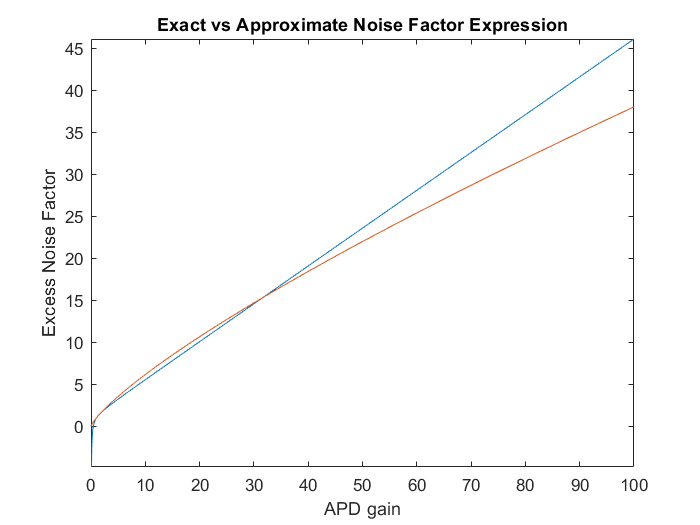

syms F_A(M) F_A_apx(M) f_diff(M)

% set the given constants
k_A = 0.45;
x = 0.79;

% create the approx and exact functions
F_A(M) = k_A*M + (1 - k_A) * (2 - 1/M);
F_A_apx(M) = M^x;

% plots
fplot(F_A, [0, 100]);

hold on 

fplot(F_A_apx,[0, 100]);
title('Exact vs Approximate Noise Factor Expression')
ylabel('Excess Noise Factor')
xlabel('APD gain')

hold off

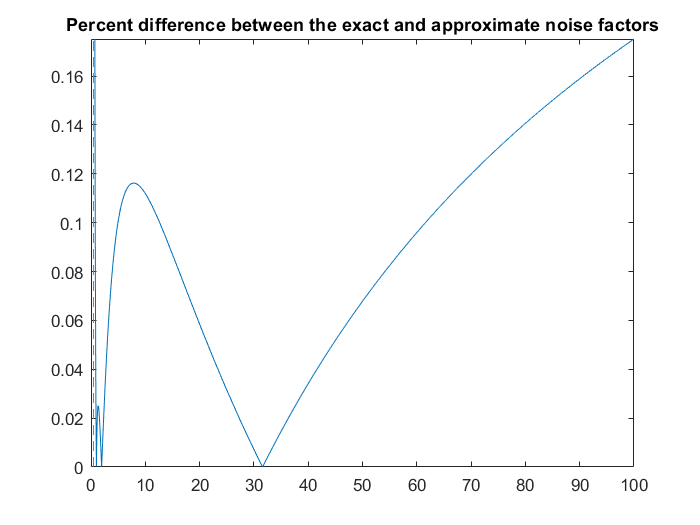

% plot of the % difference between the functions
f_diff(M) = abs(F_A(M) - F_A_apx(M)) / F_A(M);

fplot(f_diff(M), [0,100])
title('Percent difference between the exact and approximate noise factors')

part B

syms M_g(x) SNR(M) F_A

% set the constants 
R = 1; % A/W
I_d = 10e-9; % A
F_n = 2.5;
T = 300; % K
R_L = 50; % ohms
delta_f = 2e9; % Hz
P_in = 2e-6; % W
k_B = 1.38e-23;
q = 1.602e-19; % C

% create the M function derrived in the notes to find max SNR
M_g(x) = ((8 * F_n * delta_f * (k_B * T / R_L)) / (2 * q * x * delta_f * (R * P_in + I_d)))^(1 / (x + 2));

% M-value for max SNR
APD_gain = vpa(M_g(0.79))

$$APD\_gain = 18.154177880867923023991642885102$$

% SNR function
SNR(M) = 10 * log10((M * R * P_in)^2 / ((2 * q * M^2 * (k_A*M + (1 - k_A) * (2 - 1/M)) * delta_f * (R * P_in + I_d)) + (4 * F_n * delta_f * (k_B * T / R_L))));

% SNR max value based on M-value
SNR_M = vpa(SNR(APD_gain))

$$SNR\_M = 23.735395344992784343534522900102$$

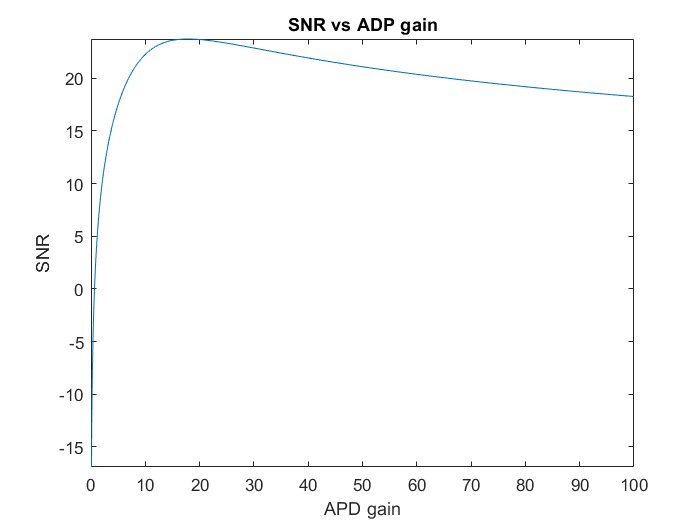

% plot of SNR 
fplot(SNR(M), [0,100])
title('SNR vs ADP gain')
ylabel('SNR')
xlabel('APD gain')